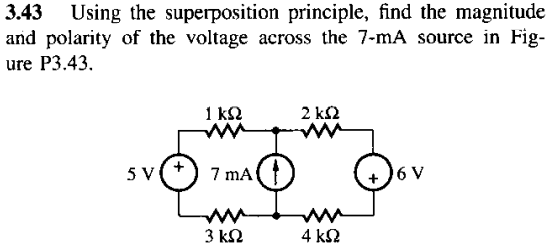

De acuerdo con el teorema de superposicion analizamos tres circuitos, ya que tenemos tres fuentes:

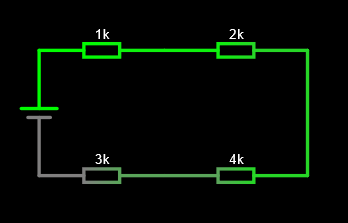

clc, clear, close all
format short g

vf1 = 5;
vf2 = 6;
If = 7e-3;

r1 = 1000;
r2 = 2000;
r3 = 3000;
r4 = 4000;

i1 = vf1/(r1+r2+r3+r4) %[A]

i1 =        0.0005


%diferencia de potencial en los nodos donde estaria la fuente de corriente
vab1 = i1*(r2+r4)

vab1 =      3


Analizamos el siguiente circuito:

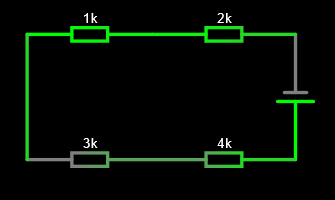

i2 = -vf2/(r1+r2+r3+r4)

i2 =       -0.0006


%diferencia de potencial en los nodos donde estaria la fuente de corriente
vab2 = i2*(r1+r3)

vab2 =          -2.4


Analizamos el ultimo circuito

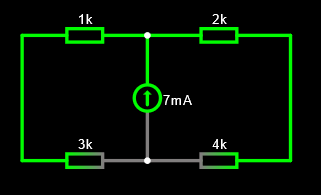

i3 = If*((r1+r3)/(r1+r2+r3+r4)) % corriente que pasa por r2 y r4

i3 =        0.0028


vab3 = i3*(r2+r4)

vab3 =          16.8


finalmente sumamos las tensiones obtenidas para obtener la tension en la fuente de corriente:

vab = vab1+vab2+vab3 %[V]

vab =          17.4


Lo verificamos en el simulador